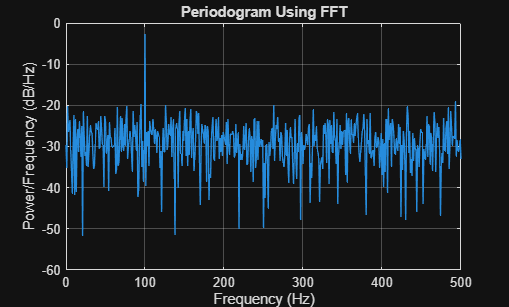

%Example of Energy Spectral Density Calculation
%By Tara, Katrina, and Justin

fs = 1000;
t = 0:1/fs:1-1/fs;
x = cos(2*pi*100*t) + randn(size(t));

N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:fs/length(x):fs/2;

plot(freq,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Frequency (Hz)")
ylabel("Power/Frequency (dB/Hz)")

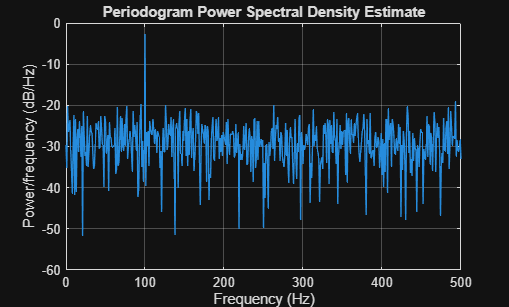


periodogram(x,rectwin(N),N,fs)


mxerr = max(psdx'-periodogram(x,rectwin(N),N,fs))

mxerr = 3.4694e-18

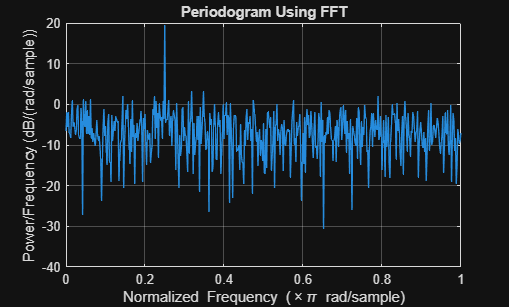


N = 1000;
n = 0:N-1;
x = cos(pi/4*n) + randn(size(n));

xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(2*pi*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:2*pi/N:pi;

plot(freq/pi,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Power/Frequency (dB/(rad/sample))")

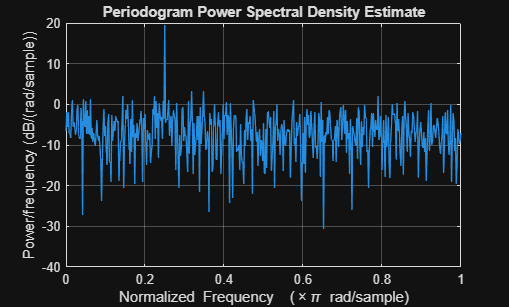


periodogram(x,rectwin(N),N)


mxerr = max(psdx'-periodogram(x,rectwin(N),N))

mxerr = 4.4409e-16

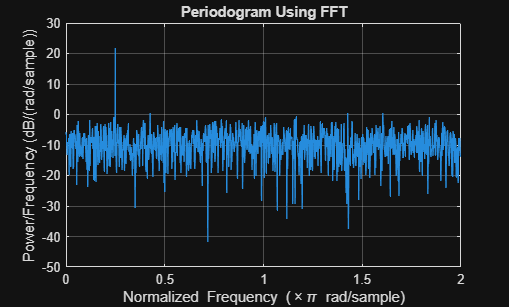


N = 1000;
n = 0:N-1;
x = exp(1j*pi/4*n) + [1 1j]*randn(2,N)/sqrt(2);

xdft = fft(x);
psdx = (1/(2*pi*N)) * abs(xdft).^2;
freq = 0:2*pi/N:2*pi-2*pi/N;

plot(freq/pi,pow2db(psdx))
grid on
title("Periodogram Using FFT")
xlabel("Normalized Frequency (\times\pi rad/sample)")
ylabel("Power/Frequency (dB/(rad/sample))")

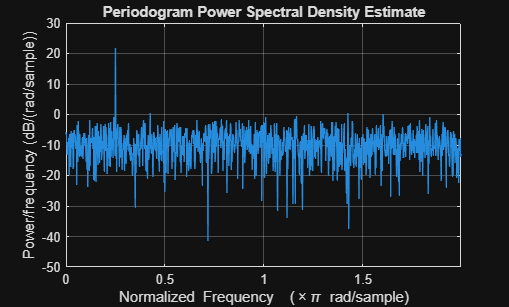


periodogram(x,rectwin(N),N,"twosided")


mxerr = max(psdx'-periodogram(x,rectwin(N),N,"twosided"))

mxerr = 2.8422e-14